# **Práctica 2**

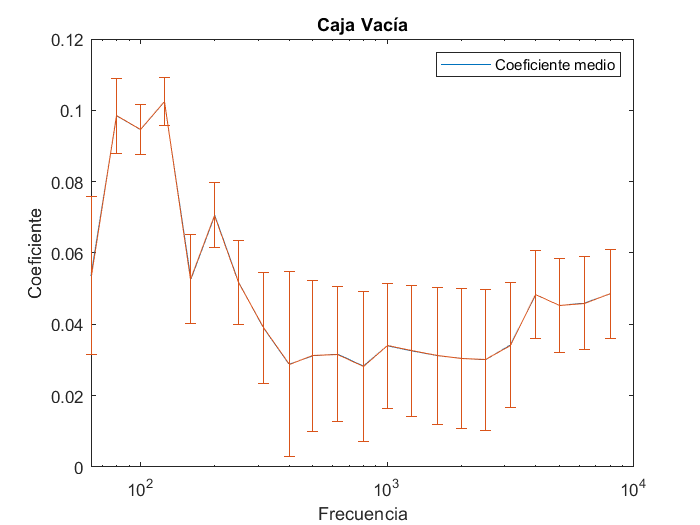

clear;

[ACV1, ACV2, ACV3, ACVm1, ECV, F]=Caja_Vacia;

[Ap11, Ap12, Ap13, APm11, EP1]=Poliester_1;

[Ap21, Ap22, Ap23, APm21, EP2]=Poliester_2;

[Ap31, Ap32, Ap33, APm31, EP3]=Poliester_3;

[Ah11, Ah12, Ah13, Ahm11, EH1]=Herakustik_1;

[Ah21, Ah22, Ah23, Ahm21, EH2] = Herakustik_2;

[Ah31, Ah32, Ah33, Ahm31, EH3] = Herakustik_3;

[ACC1, ACC2, ACC3, ACCm1, ECC] = Cilindro_Centro;

[ACE1, ACE2, ACE3, ACEm1, ECE] = Cilindro_Esquina;

[ACCC1, ACCC2, ACCC3, ACCCm1, ECCo] = Cilindro_Colgando;

[ACPP1, ACPP2, ACPP3, ACPPm1, EPS] = Cilindro_Peq_Separados;

[CPJ1, CPJ2, CPJ3, CPJm1, EPJ] = Cilindro_Peq_Juntos;

[Pol, Her, Mel] = Valores_Teoricos;

figure;
semilogx(F, ACVm1)
hold on;
errorbar(F, ACVm1, ECV);
title('Caja Vacía')
legend('Coeficiente medio')
xlabel('Frecuencia')
ylabel('Coeficiente')

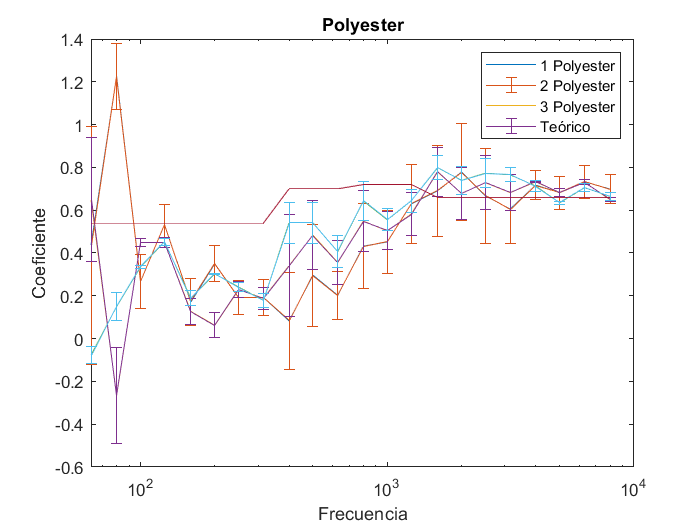


figure;
semilogx(F, APm11)
hold on
errorbar(F, APm11, EP1);
semilogx(F, APm21)
errorbar(F, APm21, EP2);
semilogx(F, APm31)
errorbar(F, APm31, EP3);
semilogx(F, Pol)
title('Polyester')
legend('1 Polyester', '2 Polyester', '3 Polyester', 'Teórico')
xlabel('Frecuencia')
ylabel('Coeficiente')

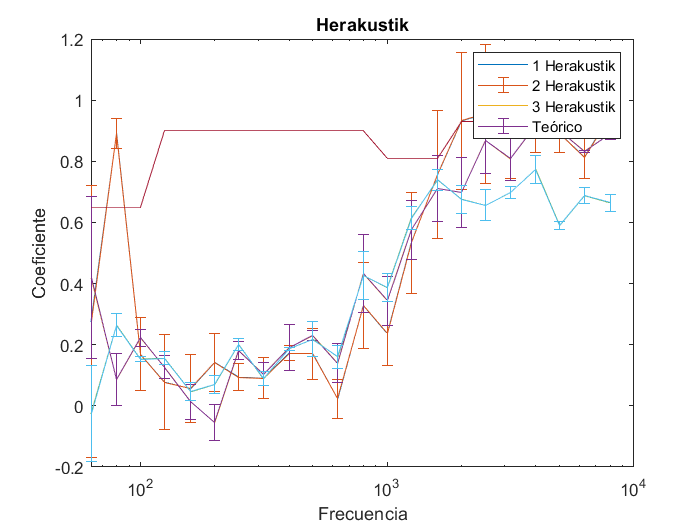


figure;
semilogx(F, Ahm11)
hold on
errorbar(F, Ahm11, EH1)
semilogx(F, Ahm21)
errorbar(F, Ahm21, EH2)
semilogx(F, Ahm31)
errorbar(F, Ahm31, EH3)
semilogx(F, Her)
title('Herakustik')
legend('1 Herakustik', '2 Herakustik', '3 Herakustik', 'Teórico')
xlabel('Frecuencia')
ylabel('Coeficiente')

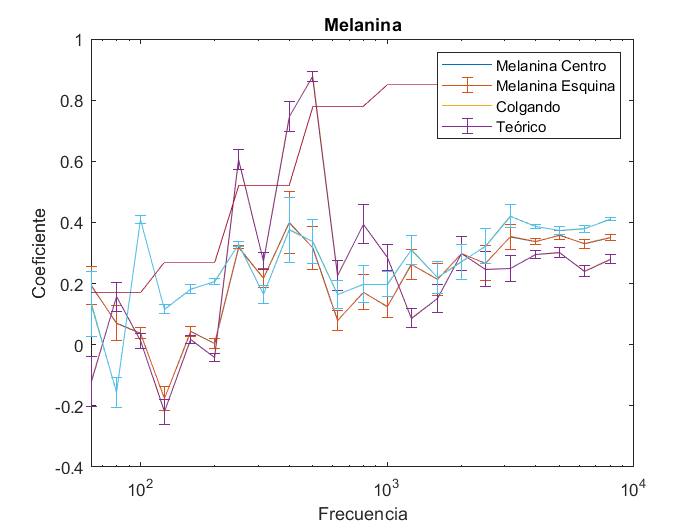


figure;
semilogx(F, ACCm1)
hold on
errorbar(F, ACCm1, ECC)
semilogx(F, ACE1)
errorbar(F, ACE1, ECE)
semilogx(F, ACCC1)
errorbar(F, ACCC1, ECCo)
semilogx(F, Mel)
title('Melanina')
legend('Melanina Centro', 'Melanina Esquina', 'Colgando', 'Teórico')
xlabel('Frecuencia')
ylabel('Coeficiente')

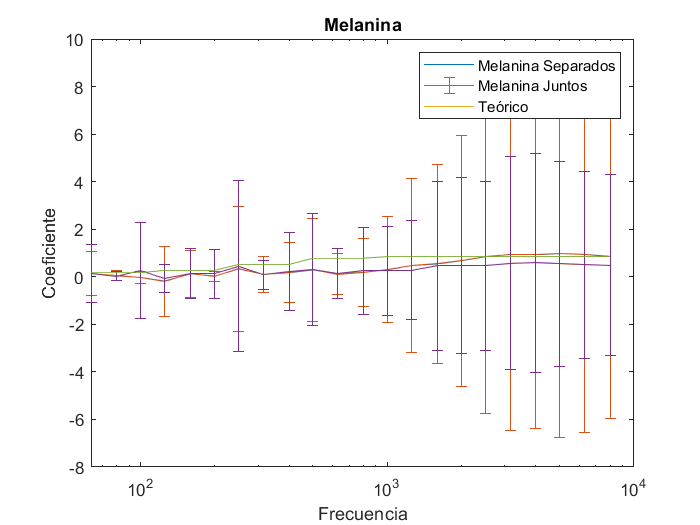


figure;
semilogx(F, ACPPm1)
hold on
errorbar(F, ACPPm1, EPS)
semilogx(F, CPJm1)
errorbar(F, CPJm1, EPJ)
semilogx(F, Mel)
title('Melanina')
legend('Melanina Separados', 'Melanina Juntos', 'Teórico')
xlabel('Frecuencia')
ylabel('Coeficiente')

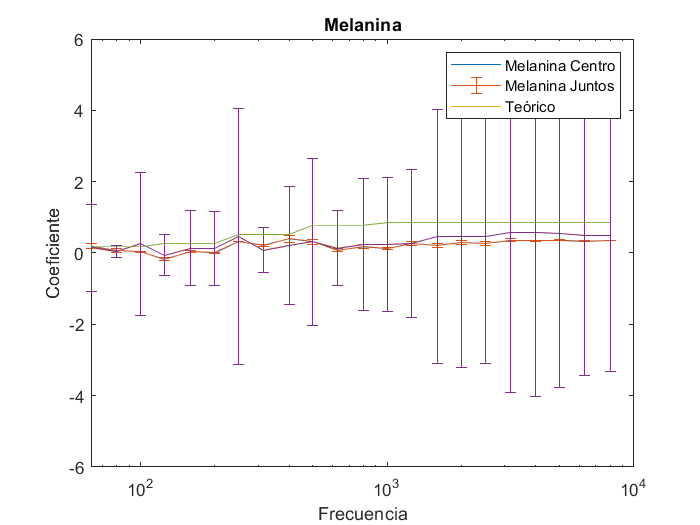


figure;
semilogx(F, ACCm1)
hold on
errorbar(F, ACCm1, ECC)
semilogx(F, CPJm1)
errorbar(F, CPJm1, EPJ)
semilogx(F, Mel)
title('Melanina')
legend('Melanina Centro', 'Melanina Juntos', 'Teórico')
xlabel('Frecuencia')
ylabel('Coeficiente')

# **1 Poliéster**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1]=Poliester_1
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

LargPol=20/100; AnchPol=15/100; AltPol=3.5/100;
VPol=AltPol*AnchPol*LargPol;

V=V-VPol;

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VP11=load('POLYESTER_B1-1.txt');
VP12=load('POLYESTER_B1-2.txt');
VP13=load('POLYESTER_B1-3.txt');

F=VP11(:,1);
T1=VP11(:,2);
T2=VP12(:,2);
T3=VP13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 2*(AnchPol*AltPol)+2*(LargPol*AltPol)+(AnchPol*LargPol);
ESuperficieMat= 2*(AnchPol*E+AltPol*E)+2*(LargPol*E+AltPol*E)+(AnchPol*E+LargPol*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end
end

# **2 Poliéster**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1]=Poliester_2
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

LargPol=20/100; AnchPol=15/100; AltPol=3.5/100;
VPol=AltPol*AnchPol*LargPol;

V=V-(2*VPol);

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VP21=load('POLYESTER_B2-1.txt');
VP22=load('POLYESTER_B2-2.txt');
VP23=load('POLYESTER_B2-3.txt');

F=VP21(:,1);
T1=VP21(:,2);
T2=VP22(:,2);
T3=VP23(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 2*(2*(AnchPol*AltPol)+2*(LargPol*AltPol)+(AnchPol*LargPol));
ESuperficieMat= 2*(2*(AnchPol*E+AltPol*E)+2*(LargPol*E+AltPol*E)+(AnchPol*E+LargPol*E));

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **3 Poliéster**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1]=Poliester_3
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

LargPol=20/100; AnchPol=15/100; AltPol=3.5/100;
VPol=AltPol*AnchPol*LargPol;

V=V-(3*VPol);

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VP31=load('POLYESTER_B3-1.txt');
VP32=load('POLYESTER_B3-2.txt');
VP33=load('POLYESTER_B3-3.txt');

F=VP31(:,1);
T1=VP31(:,2);
T2=VP32(:,2);
T3=VP33(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 3*(2*(AnchPol*AltPol)+2*(LargPol*AltPol)+(AnchPol*LargPol));
ESuperficieMat= 3*(2*(AnchPol*E+AltPol*E)+2*(LargPol*E+AltPol*E)+(AnchPol*E+LargPol*E));

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
    
end
end

# **1 Herakustik**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1]=Herakustik_1
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltHer=3.5/100; AnchHer=14/100; LargHer=24.3/100;
VHer=AltHer*AnchHer*LargHer;

V=V-(VHer);

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VH11=load('HERAKUSTIK_C1-1.txt');
VH12=load('HERAKUSTIK_C1-2.txt');
VH13=load('HERAKUSTIK_C1-3.txt');

F=VH11(:,1);
T1=VH11(:,2);
T2=VH12(:,2);
T3=VH13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 2*(AnchHer*AltHer)+2*(LargHer*AltHer)+(AnchHer*LargHer);
ESuperficieMat= 2*(AnchHer*E+AltHer*E)+2*(LargHer*E+AltHer*E)+(AnchHer*E+LargHer*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end
end

# **2 Herakustik**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Herakustik_2
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltHer=3.5/100; AnchHer=14/100; LargHer=24.3/100;
VHer=AltHer*AnchHer*LargHer;

V=V-(2*VHer);

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VH21=load('HERAKUSTIK_C2-1.txt');
VH22=load('HERAKUSTIK_C2-2.txt');
VH23=load('HERAKUSTIK_C2-3.txt');

F=VH21(:,1);
T1=VH21(:,2);
T2=VH22(:,2);
T3=VH23(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 2*(2*(AnchHer*AltHer)+2*(LargHer*AltHer)+(AnchHer*LargHer));
ESuperficieMat= 2*(2*(AnchHer*E+AltHer*E)+2*(LargHer*E+AltHer*E)+(AnchHer*E+LargHer*E));

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end
end

# **3 Herakustik**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Herakustik_3
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltHer=3.5/100; AnchHer=12.8/100; LargHer=35.5/100;
AltHer2=3.5/100; AnchHer2=14/100; LargHer2=24.3/100;

VHer=AltHer*AnchHer*LargHer;
VHer2=AltHer2*AnchHer2*LargHer2;

V=V-(2*VHer+VHer2);


A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VH31=load('HERAKUSTIK_C3-1.txt');
VH32=load('HERAKUSTIK_C3-2.txt');
VH33=load('HERAKUSTIK_C3-3.txt');

F=VH31(:,1);
T1=VH31(:,2);
T2=VH32(:,2);
T3=VH33(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 2*(2*(AnchHer*AltHer)+2*(LargHer*AltHer)+(AnchHer*LargHer))+(2*(AnchHer2*AltHer2)+2*(LargHer2*AltHer2)+(AnchHer2*LargHer2));
ESuperficieMat= 2*(2*(AnchHer*E+AltHer*E)+2*(LargHer*E+AltHer*E)+(AnchHer*E+LargHer*E))+2*(AnchHer2*E+AltHer2*E)+2*(LargHer2*E+AltHer2*E)+(AnchHer2*E+LargHer2*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **Cilindro centro**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Cilindro_Centro
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltCil=24.7/100; DiamCil=14.4/100;
VCil=pi*AltCil*(DiamCil/2)^2;

V=V-VCil;


A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VMC11=load('MELAMINA_D1_CENTRO-1.txt');
VMC12=load('MELAMINA_D1_CENTRO-2.txt');
VMC13=load('MELAMINA_D1_CENTRO-3.txt');

F=VMC11(:,1);
T1=VMC11(:,2);
T2=VMC12(:,2);
T3=VMC13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= (2*pi*AltCil*(DiamCil/2))+(pi*(DiamCil/2));
ESuperficieMat= (2*pi*(AltCil*E+(DiamCil/2)*E))+(pi*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **Cilindro esquina**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Cilindro_Esquina
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltCil=24.7/100; DiamCil=14.4/100;
VCil=pi*AltCil*(DiamCil/2)^2;

V=V-VCil;


A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VME11=load('MELAMINA_D1_ESQUINA-1.txt');
VME12=load('MELAMINA_D1_ESQUINA-2.txt');
VME13=load('MELAMINA_D1_ESQUINA-3.txt');

T1=VME11(:,2);
T2=VME12(:,2);
T3=VME13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= (2*pi*AltCil*(DiamCil/2))+(pi*(DiamCil/2));
ESuperficieMat= (2*pi*(AltCil*E+(DiamCil/2)*E))+(pi*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **Cilindro Colgando**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Cilindro_Colgando
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltCil=24.7/100; DiamCil=14.4/100;
VCil=pi*AltCil*(DiamCil/2)^2;

V=V-VCil;


A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VMC11=load('MELAMINA_D1_COLGANDO-1.txt');
VMC12=load('MELAMINA_D1_COLGANDO-2.txt');
VMC13=load('MELAMINA_D1_COLGANDO-3.txt');

T1=VMC11(:,2);
T2=VMC12(:,2);
T3=VMC13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= (2*pi*AltCil*(DiamCil/2))+(pi*(DiamCil/2));
ESuperficieMat= (2*pi*(AltCil*E+(DiamCil/2)*E))+(pi*E);

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **Cilindro Pequeños Pegados**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Cilindro_Peq_Separados
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltPeq=3.63/100; DiamPeq=3.1/100;
VCil=pi*AltPeq*(DiamPeq/2)^2;

V=V-(45*VCil);


A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);

VMPP11=load('MELAMINA_NUBES_D2B-1.txt');
VMPP12=load('MELAMINA_NUBES_D2B-2.txt');
VMPP13=load('MELAMINA_NUBES_D2B-3.txt');

T1=VMPP11(:,2);
T2=VMPP12(:,2);
T3=VMPP13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 45*((2*pi*AltPeq*(DiamPeq/2))+(pi*(((DiamPeq/2))^2)));
ESuperficieMat= 45*((2*pi*(AltPeq*E+(DiamPeq/2)*E))+(pi*E));

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end

alfam2=(alfa1+alfa2+alfa3)/3;
end

# **Cilindro Pequeños Juntos**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1] = Cilindro_Peq_Juntos
clear;

[av1, av2, av3, avm1, Eavm1, F]=Caja_Vacia;
[Alt, Anch, Larg, V, Error_V]=Valores;

AltPeq=3.63/100; DiamPeq=3.1/100;
VCil=pi*AltPeq*(DiamPeq/2)^2;

V=V-(45*VCil);

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);
Ealfam1_aux=zeros(22,1);
alfam1_aux=zeros(22,1);


VMPJ11=load('MELAMINA_NUBES_D2A_JUNTAS-1.txt');
VMPJ12=load('MELAMINA_NUBES_D2A_JUNTAS-2.txt');
VMPJ13=load('MELAMINA_NUBES_D2A_JUNTAS-3.txt');

F=VMPJ11(:,1);
T1=VMPJ11(:,2);
T2=VMPJ12(:,2);
T3=VMPJ13(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));
ESuperficie=(2*(Larg*E+Alt*E))+(Larg*E+Anch*E)+(2*(Alt*E+Anch*E));

SuperficieMat= 45*((2*pi*AltPeq*(DiamPeq/2))+(pi*(((DiamPeq/2))^2)));
ESuperficieMat= 45*((2*pi*(AltPeq*E+(DiamPeq/2)*E))+(pi*E));

ErrT=CalcError(T1, T2, T3);

Tm=(T1+T2+T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=(A1(i)-(Superficie*av1(i)))/SuperficieMat;
    alfa2(i)=(A2(i)-(Superficie*av2(i)))/SuperficieMat;
    alfa3(i)=(A3(i)-(Superficie*av3(i)))/SuperficieMat;
    alfam1(i)=(Am(i)-(Superficie*avm1(i)))/SuperficieMat;
    
    Ealfam1_aux(i)=Superficie*Eavm1(i)+avm1(i)*ESuperficie;
    alfam1_aux(i)=Am(i)-(Superficie*avm1(i));
    Ealfam1_aux1=EAm(i)-Ealfam1_aux(i);
    Ealfam1(i)=(alfam1_aux(i)*ESuperficieMat + SuperficieMat*Ealfam1_aux1) / SuperficieMat^2;
end
end

# **Valores**

function [Alt, Anch, Larg, V, Error_V]=Valores
Larg=110.5*10^-2;
ELarg=0.01;
Anch=82.6*10^-2;
EAnch=0.01;
Alt=59.6*10^-2;
EAlt=0.01;

V_Aux=Alt*Anch;
V=Alt*Larg*Anch;

Error_V_aux=EAlt*Anch+Alt*EAnch;
Error_V=Error_V_aux*Larg+ELarg*V_Aux;

end

# **Caja Vacía**

function [alfa1, alfa2, alfa3, alfam1, Ealfam1, F]=Caja_Vacia
[Alt, Anch, Larg, V, Error_V]=Valores;

A1=zeros(22,1);
A2=zeros(22,1);
A3=zeros(22,1);
Am=zeros(22,1);
EAm=zeros(22,1);

alfa1=zeros(22,1);
alfa2=zeros(22,1);
alfa3=zeros(22,1);
alfam1=zeros(22,1);
Ealfam1=zeros(22,1);

VA1=load("VACIA_A-1.txt");
VA2=load("VACIA_A-2.txt");
VA3=load("VACIA_A-3.txt");

F=VA1(:,1);
T1=VA1(:,2);
T2=VA2(:,2);
T3=VA3(:,2);

E=0.01;
Superficie = ((2*(Larg*Alt)+(Larg*Anch)+2*(Alt*Anch)));

ErrT = CalcError(T1, T2, T3);

Tm=(T1 + T2 + T3)/3;

for i=1:22
    A1(i)=(0.161*V)/T1(i);
    A2(i)=(0.161*V)/T2(i);
    A3(i)=(0.161*V)/T3(i);
    Am(i)=(0.161*V)/Tm(i);
    
    EAm(i)=((0.161*V)*ErrT(i)+Tm(i)*Error_V )/ V^2;
    
    alfa1(i)=A1(i)/Superficie;
    alfa2(i)=A2(i)/Superficie;
    alfa3(i)=A3(i)/Superficie;
    alfam1(i)=Am(i)/Superficie;
    
    Ealfam1(i)=(Am(i)*E + Superficie*EAm(i))/(Superficie^2);
end
end

# **Errores**

# **Valores Teóricos**

function [Poliester, Herakustik, Melanina] = Valores_Teoricos
Poliester = [0.54, 0.54, 0.54, 0.54, 0.54, 0.54, 0.54, 0.54, 0.7, 0.7, 0.7, 0.72, 0.72, 0.72, 0.66, 0.66, 0.66, 0.66, 0.66, 0.66, 0.66, 0.66];

Herakustik = [0.65, 0.65, 0.65, 0.9, 0.9, 0.9, 0.9, 0.9, 0.9, 0.9, 0.9, 0.9, 0.81, 0.81, 0.81, 0.93, 0.93, 0.93, 0.93, 0.93, 0.93, 0.93];

Melanina = [0.17, 0.17, 0.17, 0.27, 0.27, 0.27, 0.52, 0.52, 0.52, 0.78, 0.78, 0.78, 0.85, 0.85, 0.85, 0.85, 0.85, 0.85, 0.85, 0.85, 0.85, 0.85];

end

# **Error Tiempos**

function ErrT=CalcError(T1, T2, T3)
ErrT=zeros(22,1);
for i=1:22
    T11=T1(i);
    T22=T2(i);
    T33=T3(i);
    
    Tmax1=max(T11,T22);
    Tmax=max(Tmax1, T33);

    Tmin1=min(T11, T22);
    Tmin=min(Tmin1, T33);
    
    TT=Tmax-Tmin;
    TTT=TT/2;
    
    ErrT(i)=TTT;
      
end
end